# Reporte 3. Problema 2.

## Integrantes

- **Arellano Paz Ángel Ulises **

- **García Arteaga Alejandro **

- **Pérez Aboytes David **

- **Quijano Gutiérrez Luis Humberto **

- **Soto García Pablo Yael **

## Desarrollo

En clase has revisado la implementación de un FIS tipo-I al siguiente [ejemplo](https://www.mathworks.com/help/fuzzy/fuzzy-pid-control-with-type-2-fis.html#FuzzyPIDControlWithType2FISExample-2). Reproduce la implementación que se encuentra en la misma [página](https://www.mathworks.com/help/fuzzy/fuzzy-pid-control-with-type-2-fis.html#FuzzyPIDControlWithType2FISExample-3) de dicho FIS utilizando funciones de membresía tipo-II. Adjunta un enlace a tu página html donde se encuentre la implementación.

clear all 
close all

Creamos un Sistema de Interferencia Difusa tipo I usando "sugfis"

close all
clear all
clc

Las variables de entrada del FIS 

fis1 = sugfis;
fis1 = addInput(fis1,[-1 1],'Name','E');
fis1 = addInput(fis1,[-1 1],'Name','delE');

Agregamos Funciones de Membresia a cada entrada en forma de Trapecio (elegido arbitrariamente)

Los nombres significan Negativo (N), Cero (Z) y Postivo (P)

fis1 = addMF(fis1,'E','trimf',[-2 -1 0],'Name','N');
fis1 = addMF(fis1,'E','trimf',[-1 0 1],'Name','Z');
fis1 = addMF(fis1,'E','trimf',[0 1 2],'Name','P');
fis1 = addMF(fis1,'delE','trimf',[-2 -1 0],'Name','N');
fis1 = addMF(fis1,'delE','trimf',[-1 0 1],'Name','Z');
fis1 = addMF(fis1,'delE','trimf',[0 1 2],'Name','P');

Graficas las Funciones de Membresia de las entradas

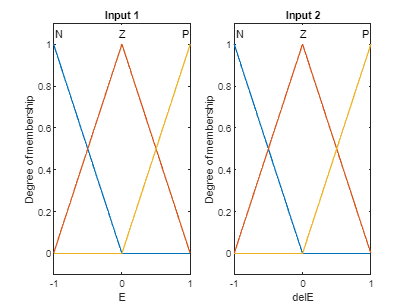

figure
subplot(1,2,1)
plotmf(fis1,'input',1)
title('Input 1')
subplot(1,2,2)
plotmf(fis1,'input',2)
title('Input 2')

Y la varable de salida  

fis1 = addOutput(fis1,[-2 2],'Name','U');

Agregamos funciones constantes y distribuidas de forma uniforme a salida. Los nombres significan Negativo Grande (NG), Negativo Mediano (NM), Negativo Chico (NC), Cero (Z), Postiuvo Chicop (PC), Positivo Mediano (PM), Positivo Grande (PG)

fis1 = addMF(fis1,'U','constant',-1,'Name','NG');
fis1 = addMF(fis1,'U','constant',-0.5,'Name','NM');
fis1 = addMF(fis1,'U','constant',0,'Name','Z');
fis1 = addMF(fis1,'U','constant',0.5,'Name','PM');
fis1 = addMF(fis1,'U','constant',1,'Name','PG');

Agregamos las reglas del FIS para tener un Control

rules = [...
    "E==N & delE==N => U=NG"; ...
    "E==Z & delE==N => U=NM"; ...
    "E==P & delE==N => U=Z"; ...
    "E==N & delE==Z => U=NM"; ...
    "E==Z & delE==Z => U=Z"; ...
    "E==P & delE==Z => U=PM"; ...
    "E==N & delE==P => U=Z"; ...
    "E==Z & delE==P => U=PM"; ...
    "E==P & delE==P => U=PG" ...
    ];
fis1 = addRule(fis1,rules);

Graficamos la Superficie de Control 

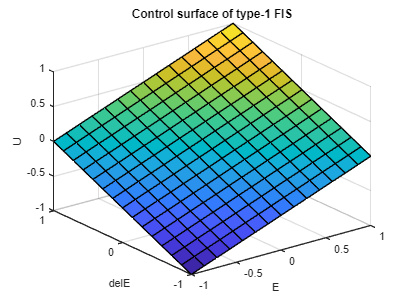

figure
gensurf(fis1)
title('Control surface of type-1 FIS')

Ahora lo hacemos Tipo 2, con lo que buscamos tener un intervalo, un rango de valores entre los cuales estara el grado de pertenencia 

fis2 = convertToType2(fis1);

El sistema tipo 2 Sugeno utiliza funciones de pertenencia de tipo 2 para las variables de entrada y funciones de pertenencia de tipo 1 para las variables de salida. Para definir la incertidumbre establecemos factores de escala

scale = [0.2 0.9 0.2;0.3 0.9 0.3];
for i = 1:length(fis2.Inputs)
    for j = 1:length(fis2.Inputs(i).MembershipFunctions)
        fis2.Inputs(i).MembershipFunctions(j).LowerLag = 0;
        fis2.Inputs(i).MembershipFunctions(j).LowerScale = scale(i,j);
    end
end

Trazamos las funciones de pertenencia de entrada de tipo 2.

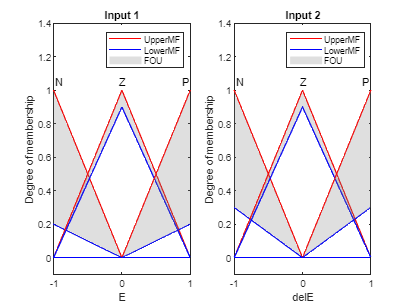

figure
subplot(1,2,1)
plotmf(fis2,'input',1)
title('Input 1')
subplot(1,2,2)
plotmf(fis2,'input',2)
title('Input 2')

Al agregar incertidumbre tenemos la Superfice de Control de la siguiente forma 

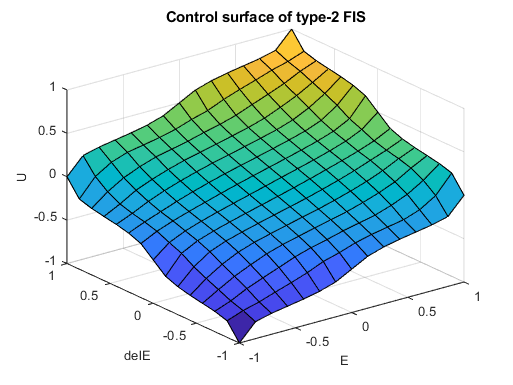

figure
gensurf(fis2)
title('Control surface of type-2 FIS')

Como analisis extra,  proponemos una forma distinta de analizar usando funciones tipo 2

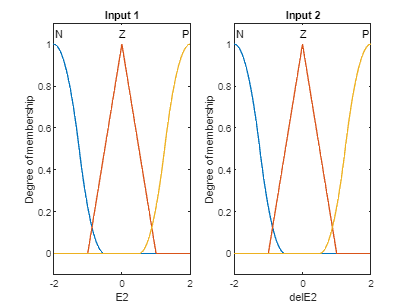

fis2 = sugfis;
fis2 = addInput(fis2,[-2 2],'Name','E2');
fis2 = addInput(fis2,[-2 2],'Name','delE2');

fis2 = addMF(fis2,'E2','zmf',[-2 -0.5],'Name','N');
fis2 = addMF(fis2,'E2','trimf',[-1 0 1],'Name','Z');
fis2 = addMF(fis2,'E2','smf',[0.5 2],'Name','P');
fis2 = addMF(fis2,'delE2','zmf',[-2 -0.5],'Name','N');
fis2 = addMF(fis2,'delE2','trimf',[-1 0 1],'Name','Z');
fis2 = addMF(fis2,'delE2','smf',[0.5 2],'Name','P');

figure
subplot(1,2,1)
plotmf(fis2,'input',1)
title('Input 1')
subplot(1,2,2)
plotmf(fis2,'input',2)
title('Input 2')

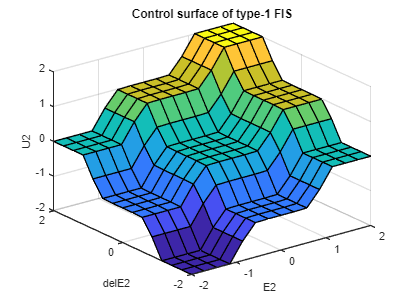


fis2 = addOutput(fis2,[-2 2],'Name','U2');

fis2 = addMF(fis2,'U2','constant',-2,'Name','NG');
fis2 = addMF(fis2,'U2','constant',-1,'Name','NM');
fis2 = addMF(fis2,'U2','constant',0,'Name','Z');
fis2 = addMF(fis2,'U2','constant',1,'Name','PM');
fis2 = addMF(fis2,'U2','constant',2,'Name','PG');

rules2 = [...
    "E2==N & delE2==N => U2=NG"; ...
    "E2==Z & delE2==N => U2=NM"; ...
    "E2==P & delE2==N => U2=Z"; ...
    "E2==N & delE2==Z => U2=NM"; ...
    "E2==Z & delE2==Z => U2=Z"; ...
    "E2==P & delE2==Z => U2=PM"; ...
    "E2==N & delE2==P => U2=Z"; ...
    "E2==Z & delE2==P => U2=PM"; ...
    "E2==P & delE2==P => U2=PG" ...
    ];
fis2 = addRule(fis2,rules2);

figure
gensurf(fis2)
title('Control surface of type-1 FIS')

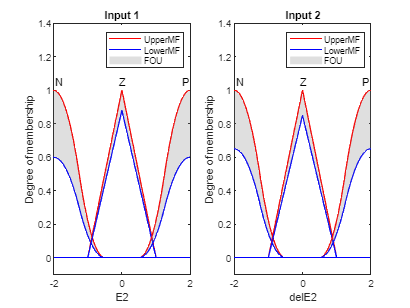


fis3 = convertToType2(fis2);

scale = [0.6 0.88 0.6;0.65 0.85 0.65];
for i = 1:length(fis3.Inputs)
    for j = 1:length(fis3.Inputs(i).MembershipFunctions)
        fis3.Inputs(i).MembershipFunctions(j).LowerLag = 0;
        fis3.Inputs(i).MembershipFunctions(j).LowerScale = scale(i,j);
    end
end

figure
subplot(1,2,1)
plotmf(fis3,'input',1)
title('Input 1')
subplot(1,2,2)
plotmf(fis3,'input',2)
title('Input 2')

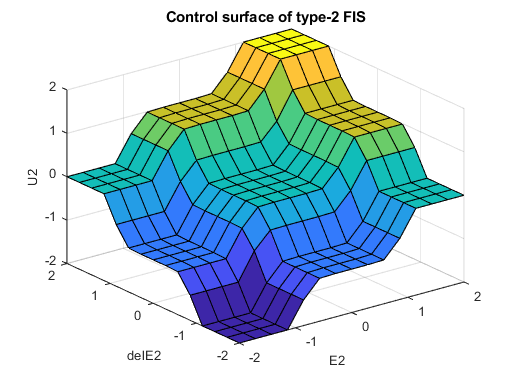


figure
gensurf(fis3)
title('Control surface of type-2 FIS')